# Subsonic Theoretical Calculations

## Setup

clear; clc; close all

% constants
AREA_RATIOS = [1.06, 1.00, 1.05, 1.15, 1.23, 1.27, 1.28]; % A/A*
TAP_POS_Xs = [24.7, 36.6, 48.3, 61.0, 73.7, 86.4, 99.1]; % mm

% data
data = matfile("data/subsonic/pressure_total_port_2.mat"); % check file
data1 = matfile("data/subsonic/pressure_total_port_1.mat");
%data2 = matfile("data/subsonic/pressure_total_port_2.mat");
data3 = matfile("data/subsonic/pressure_total_port_3.mat");
data4 = matfile("data/subsonic/pressure_total_port_4.mat");
data5 = matfile("data/subsonic/pressure_total_port_5.mat");
data6 = matfile("data/subsonic/pressure_total_port_6.mat");
data7 = matfile("data/subsonic/pressure_total_port_7.mat");


## Main

% get reference values
p_total_0 = data.totalP;
p_static_0 = data.dataP_mean(1,2); % check index


u_0 = flow_pressure(p_total_0, p_static_0); % compute flow velocity at reference using bernoulli law

% theoretical pressure and mach distributions
u_dist_subsonic_theo = flow(u_0, AREA_RATIOS) % flow velocity distribution

u_dist_subsonic_theo =   120.9547  128.2120  122.1067  111.4887  104.2374  100.9543  100.1656


p_dist_subsonic_theo = pressure(p_static_0, u_dist_subsonic_theo) % pressure distribution

p_dist_subsonic_theo = 	1.0e+04 *

    8.2123    8.1016    8.1952    8.3471    8.4429    8.4842    8.4939


m_dist_subsonic_theo = mach(u_dist_subsonic_theo, p_dist_subsonic_theo) % mach number distribution 

m_dist_subsonic_theo =     0.3948    0.4214    0.3990    0.3610    0.3356    0.3242    0.3215


GAMMA = 1.4;
RHO = 1.225;

%experimental pressure and mach distributions
u2 = sqrt(2*(p_total_0 - p_static_0)/RHO);
u_dist_sub_exp = u2 * AREA_RATIOS.^-1;

tempu = 0.5*((data.dataP_std(1,2))./(p_total_0 - p_static_0))*(u2);

unc_u_dist = tempu.^-1;

p_vals2 = data.dataP_mean(1,1:7); 

p_unc2 = data.dataP_std(1,1:7);

a = sqrt((GAMMA*p_vals2)./RHO);
unc_a = 0.5.*((GAMMA.*p_unc2)./(RHO)).*(RHO./(GAMMA.*p_vals2)).*(a);

mach_dist_exp = u_dist_sub_exp ./ a;
mach_unc = (mach_dist_exp).*sqrt((unc_u_dist./u_dist_sub_exp).^2+(unc_a./a).^2);
%unc_a = final_unc;
%temp2 = (unc_totalP).^2 + (p_unc2).^2;
%unc_u_dist = sqrt(temp2);

## Plots

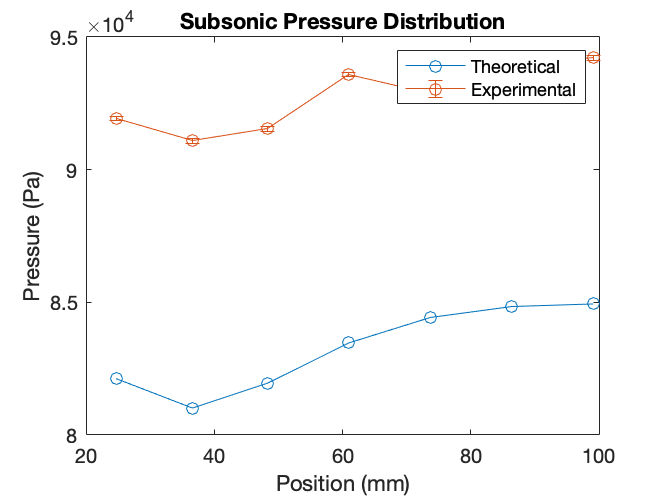


%% pressure distribution
figure
% theoretical plot
plot(TAP_POS_Xs, p_dist_subsonic_theo, "-o")
title("Subsonic Pressure Distribution")
xlabel("Position (mm)");
ylabel("Pressure (Pa)");
hold on;

% experimental plot
p_dist_subsonic_exp.val = p_vals2; 
p_dist_subsonic_exp.unc = p_unc2; 
errorbar(TAP_POS_Xs, p_dist_subsonic_exp.val, p_dist_subsonic_exp.unc, "-o");
legend("Theoretical", "Experimental");
hold off;

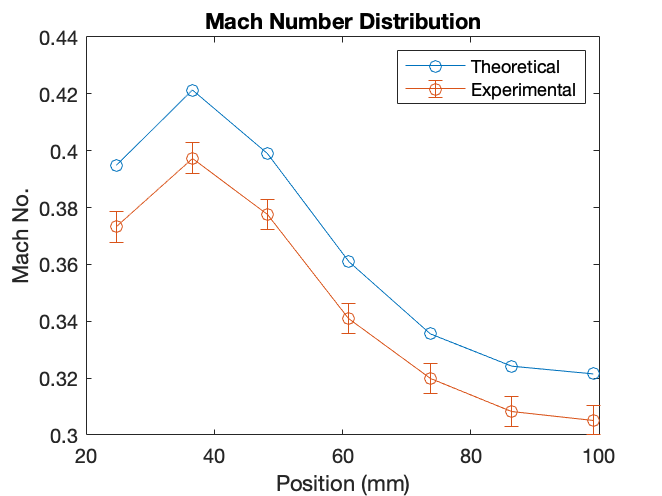


%% mach distribution
figure
% theoretical plot
plot(TAP_POS_Xs, m_dist_subsonic_theo, "-o");
title("Mach Number Distribution");
xlabel("Position (mm)");
ylabel("Mach No.");
hold on;

% experimental plot
m_dist_subsonic_exp.val = mach_dist_exp; 
m_dist_subsonic_exp.unc = mach_unc; % placeholder
errorbar(TAP_POS_Xs, m_dist_subsonic_exp.val, m_dist_subsonic_exp.unc, "-o");
legend("Theoretical", "Experimental");
hold off;

## Functions

function p = pressure(p_0, u)
    % Computes the static pressure from bernoulli equation (assumes isentropic flow)
    %
    % Args:
    %   p_0: Static pressure at reference point
    %   u: flow velocity at point where pressure is to be calculated

    RHO = 1.225; % kg/m^3
    
    p = p_0 - 1/2*RHO*u.^2;
end

function u = flow_pressure(p_total, p_static)
    % Computes the flow velocity from bernoulli law using total pressure
    % and static pressure measured at the same point
    % Args:
    %   p_total: Total pressure (static + dynamic) [Pa]
    %   p_static: Static pressure [Pa]
    
    RHO = 1.225; % kg/m^3

    u = sqrt(2*(p_total - p_static)/RHO);
end

function u = flow(u_0, area_ratio)
    % Computes the flow velocity from continuity equation (assumes incompressible flow) 
    % using reference flow velocity and ratio between area at point of
    % interest and reference chamber area.
    % 
    % Args:
    %   u_0: flow velocity at reference [m/s]
    %   area_ratio: ratio between area of chamber at point where 'u' is
    %       being calculated and chamber area where 'u_0' was obtained

    u = u_0 * area_ratio.^-1;
end

function m = mach(u, p)
    % Computes the mach number.
    %
    % Args:
    %   u: local flow velocity [m/s]
    %   p: local static pressure [Pa]
    
    v = sound(p);
    m = u ./ v;
end

function v = sound(p)
    % Computes the mach number for a given pressure.
    %
    % Args:
    %   p: local static pressure [Pa]

    RHO = 1.225; % density of standard air kg/m^3
    GAMMA = 1.4; % heat capacity ratio of standard air

    v = sqrt(GAMMA*p/RHO);
end
